# **3D visualisation of APT data**

**3D visualisation, turntable animation **

In order to reconstruct an APT tip in 3D, first a mass spectrum needs to be ranged, see the instructions in the live script ***FirstSteps***.

If the user wants to work with a saved ranged mass spectrum, the mass spectrum figure needs to be opened. Then the mass spectrum plot must be selected and the command *spec = gco; *executed. To ensure a proper functionality of the subsequent steps, both the pos file and the *colorScheme* need to be loaded (if not already present in the workspace):

load colorScheme.mat;
posIn = posToTable;

## Allocating ions to the ranges of the mass spectrum

The function *posAllocateRange* takes a pos and a range variable and allocates ion hits to it. First, the defined ranges of the mass spectrum need to be extracted, therefore *rangesExtractFromMassSpec* must be executed in advance.

rng = rangesExtractFromMassSpec(spec); % generates a table with extracted ranges

There are two options availabe for the allocation of the ranges. The option *'decompose'* generates a table, where every complex ion is decomposed and therefore the number of rows increases compared to the initial pos file. When using *'raw'* as option input, the complex ions do not get decomposed and the number of rows stays unchanged.

options = 'raw'; 
pos = posAllocateRange(posIn,rng,options); % takes a pos and a range variable and allocates ion hits to it
 

## 3D visualisation of reconstructed atom probe data

For the subsquent 3D visualisation, the function *scatterPlotPosData* is needed.

Besides the *pos* and *colorScheme *inputs, also the *species* and *sample* are mandatory inputs. The input *sample* specifies the subset, which should be plotted. A value <1 represents a fraction of the overall number of atoms (e.g. 0.5 correlates to 50 % of the total number), and a value >1 specifies the number of atoms to be plotted. 

It is possible to either plot one or more species in one plot or simultanesously generate several plots of different species, but still in one figure.

### Plotting of one species

When plotting one species, the species needs to be specified. This can be done within the live script by inserting the symbol without any brackets or quotes in the following edit field.

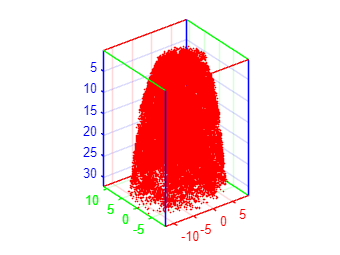

species = 'H2'; % which ion/atom species should be plotted
sample = 0.5; % subset of atoms either as a fraction (value ≤1) or number of atoms (value >1)
size = 1; % size of the single atoms in the plot
[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size);

### Plotting of more species in one plot

For plotting more than one species in **one plot**, the axes of the figure need to be specified in the command. Also, the species must be inserted in the following way: for example {'Fe','C'} for the visualisation of Fe and C.

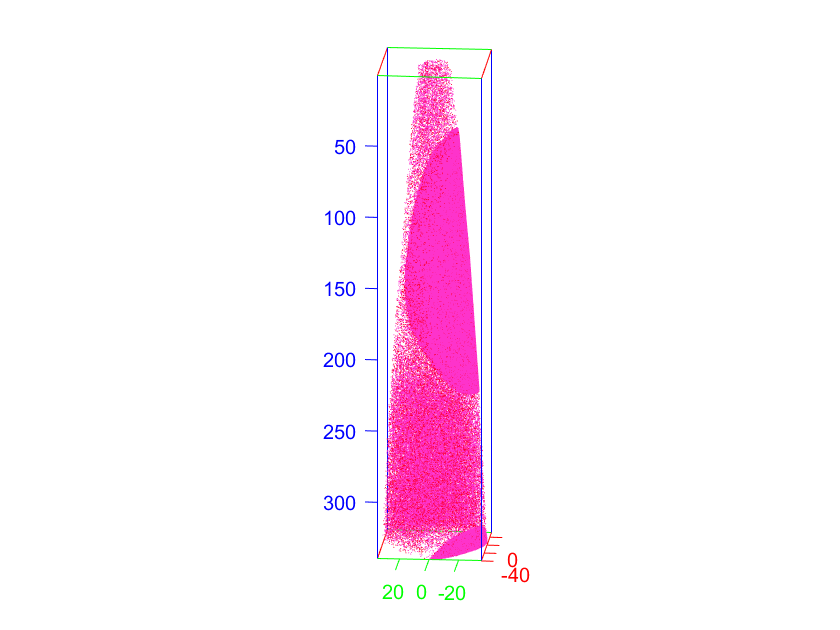

species = {'Cr','Mo'}; % which ion/atom species should be plotted in one plot; several species: {'A','B','C'}
sample = 1; % subset of atoms either as a fraction (value <1) or number of atoms (value >1)
size = 1; % size of the single atoms in the plot
[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size,axes(figure()));

### Plotting of more species in more plots

For the plotting of more than one species, no axes input must be inserted. The input of the species is the same an in the previous case. The visualisation of several species in separated plots comes in handy if the user wants to overlook particular regions, where several species are enriched or depleted.

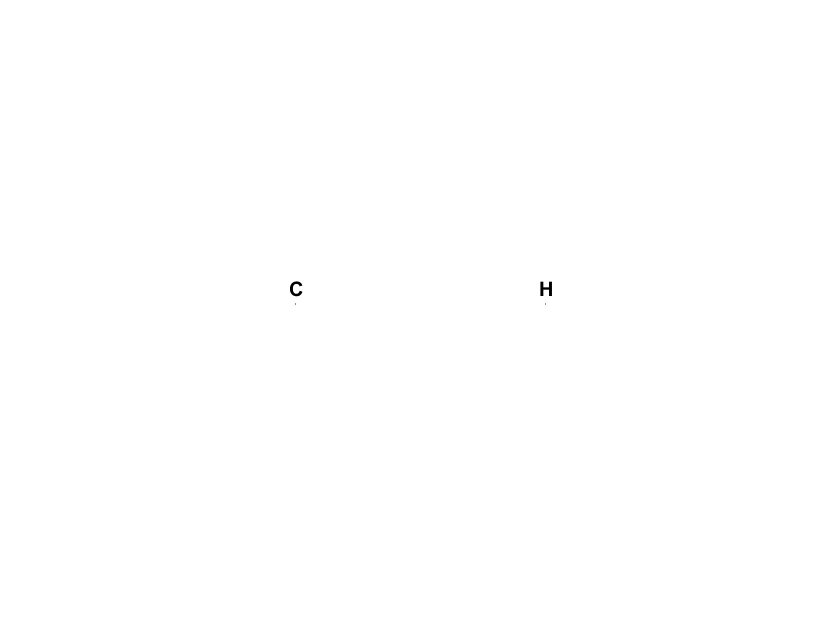

species = {'C','H'}; % which ion/atom species should be plotted in several plots; several species: {'A','B','C'}
sample = 1; % subset of atoms either as a fraction (value <1) or number of atoms (value >1)
size = 1; % size of the single atoms in the plot
[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size);

### Turntable animation of the reconstructed tip

For the illustration/presentation of areas of heterogeneity and others, a turntable animation is very useful. Therefore, the function *movieCreateTurntableAnimation(deg,frameRate,fileName)* should be used. The inputs *frameRate* and *fileName* are optional.

deg = 5; % select the step size in degrees between two frames
frameRate = 20; % select the desired frame rate, the unit is frames per second
mov = movieCreateTurntableAnimation(deg,frameRate);
 

### Change the appearance of the plot

The plot of the reconstructed APT tip is a genreal figure in Matlab. Consequently, the standard functions to change the view can be applied.

view(0,0);  % change the view on your tip
camroll(-90); % rotate camera about view axis
set(gca,'visible','off'); % make the current axes invisible
 